Problem 1.1

syms z x z_inverse y Y

% Define the difference equation
eqn = Y - x - 2.5 * z_inverse * Y == 0;

% Solve the equation for Y(z)
Y_z = solve(eqn, Y);

% Extract the transfer function
H_z = Y_z / x;

% Display the transfer function
disp('Transfer Function H(z):');
pretty(H_z);

num=[1,0];
denom=[1,-2.5]
H=tf(num, denom,1)
figure;
zplane(num,denom);
title('pole-zero plot')

R0 = 2.5;
R1=0.5
R2=1.2
R3=1 % Adjust R0 as needed

%  Z-transform of the difference equation
H_z = 1 / (1 - R0 * z^(-1));

% inverse Z-transform to find the time-domain equation
y_n = iztrans(H_z, z, n);

disp('Time-Domain Equation:');
disp(y_n);

numerator = 1;
denominator = [1, -R0];

% Plot the pole-zero plot
figure;
zplane(numerator, denominator);
title('Pole-Zero Plot (R=2.5)');
xlabel('Real');
ylabel('Imaginary');
grid on;
numerator = 1;
denominator = [1, -R1];
H_z1 = 1 / (1 - R1 * z^(-1));
y_n1 = iztrans(H_z1, z, n);
disp('Time-Domain Equation:');
disp(y_n1);




% Plot the pole-zero plot
figure;
zplane(numerator, denominator);
title('Pole-Zero Plot(R=0.5)');
xlabel('Real');
ylabel('Imaginary');
grid on;
numerator = 1;
denominator = [1, -R2];
H_z2 = 1 / (1 - R2 * z^(-1));
y_n2 = iztrans(H_z2, z, n);
disp('Time-Domain Equation:');
disp(y_n2);



% Plot the pole-zero plot
figure;
zplane(numerator, denominator);
title('Pole-Zero Plot(R=1.2)');
xlabel('Real');
ylabel('Imaginary');
grid on;
numerator = 1;
denominator = [1, -R3];
H_z3 = 1 / (1 - R3 * z^(-1));
y_n3 = iztrans(H_z3, z, n);
disp('Time-Domain Equation:');
disp(y_n3);


% Plot the pole-zero plot
figure;
zplane(numerator, denominator);
title('Pole-Zero Plot(R=1)');
xlabel('Real');
ylabel('Imaginary');
grid on;

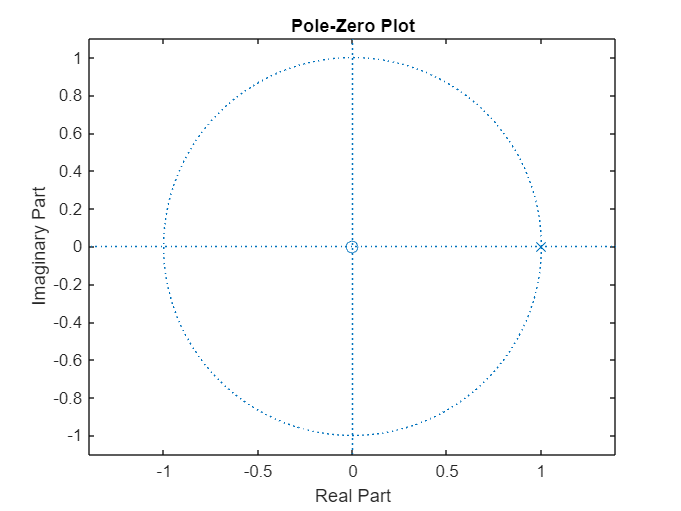

R0 = 2.5;  
y = 1;
n = 1;

while y < 1000000
    y = 1 + (R0 * y);
    n = n + 1;
end

disp([num2str(n) ' no of days needed to reach 1 million new daily infections.']);

Problem 1.2

syms y(n) z R0  % define system and variables
assume(n>=0 & in(n,"integer"))
f = y(n) - R0*y(n-1) - kroneckerDelta(n); % define eqn
fZT = ztrans(f,n,z); % take z transform
syms yZT
fZT = subs(fZT,ztrans(y(n),n,z),yZT); % substitute yzt transform in terms of ztransform
yZT = solve(fZT,yZT); % write in terms of Z
ySolz = subs(yZT,[y(-1)], [0]);
r0 = 1;
b = -1;
a = [-1, r0];
zplane(b,a) % Pole zero plot
ySol = iztrans(yZT,z,n); % take inverse z transform
ySol = simplify(ySol); % simplify
ySol = subs(ySol,[y(-1)],[0]) % put intial conditions

$$ySol = \left\{ \begin{array}{cl} \delta_{n,0} & \text{ if }R_{0}=0\\ {R_{0}}^{n} & \text{ if }R_{0}\neq 0 \end{array}\right.$$

Problem 1.3


ySol1 = subs(ySol,[y(-1) R0],[0 2.5]) % put intial conditions

$$ySol1 = {\left(\frac{5}{2}\right)}^{n}$$

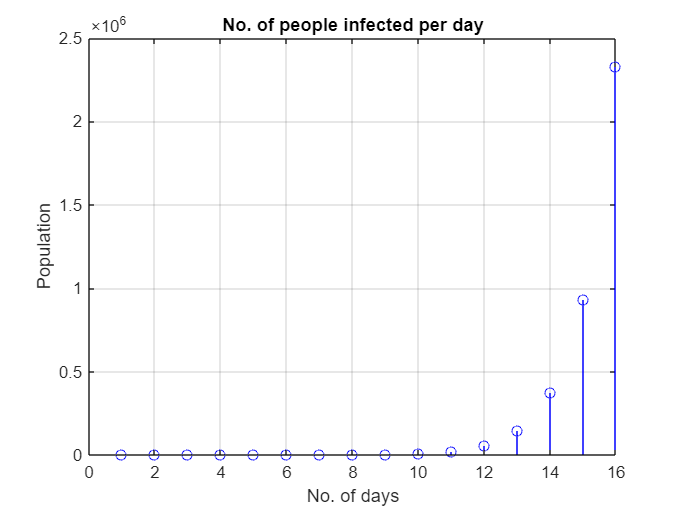

nValues = 1:16;
ySolValues = subs(ySol1,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues);
stem(nValues, ySolValues,"b")
title("No. of people infected per day")
ylabel("Population")
xlabel("No. of days")
grid on

figure;
ySolValues(15)

ans = 9.3132e+05

ySolValues(16)

ans = 2.3283e+06

% ansr is 16 days

Problem 1.4

syms y(n) z R0(n)  % define system and variables
assume(n>=0 & in(n,"integer"))
f1 = y(n) - R0(n)*y(n-1) - kroneckerDelta(n) % define eqn

$$f1 = y\left(n\right)-y\left(n-1\right)\,R_{0}\left(n\right)-\delta_{n,0}$$

days = 50;
syms r
f1 =  subs(f1,R0(n),r); 
r = solve(f1,r);
Y = [2, 4, 5, 6, 10, 19, 65, 78, 114, 137, 140, 144, 173, 204, 225, 245, 254, 287, 307, 341, 368, 373,387, 404, 423, 460, 506, 571, 596, 614, 658, 688, 755, 807, 835, 855, 1007, 1143, 1245, 1391,1607, 1806, 1907, 2111, 2191, 2340, 2528, 2710, 2772, 2865] 
;% find data for first 50 days frm covid website
rT = zeros(1,days); % put days here
for i =1:length(Y)-1
    r1 = subs(r,n,i);
    rT(i) = subs(r1,[y(i-1) y(i)],[Y(i) Y(i+1)]);
end
R_avg = sum(rT)/length(rT)

R_avg = 1.1700

Problem 1.5

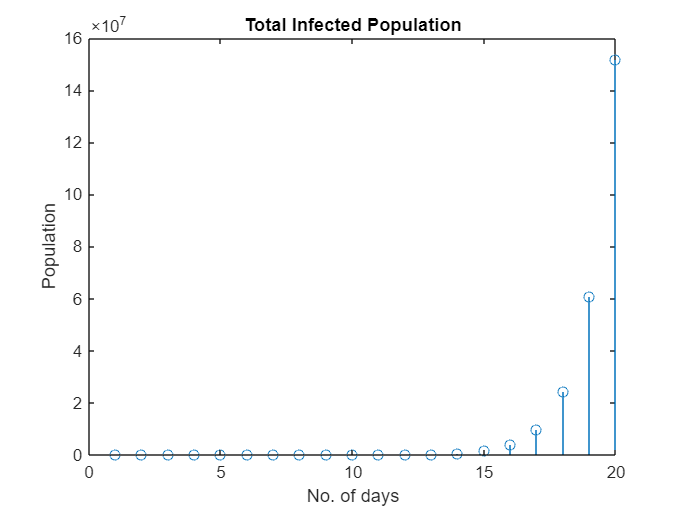

% intergrator filter
b1 = 1;
a1 = [1 -1];
nValues = 1:20;
ySolValues = subs(ySol1,n,nValues);
ySolValues = double(ySolValues);
ySolValues = real(ySolValues); % data for 1st 20 days
I = filter(b1,a1,ySolValues); % intergrator filter
stem(I)
title("Total Infected Population")
ylabel("Population")
xlabel("No. of days")

figure;
Total_infected_people = I(20)

Total_infected_people = 1.5158e+08

Problem 2.1

ak = [0.1,  0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1]; %5 coeffs
b2 = 1;
a2 = [1 -ak];
sys2 = tf(b2,a2,1,"Variable" ,"z^-1") % trasnfer function 

sys2 =
 
                                                                         1
  -----------------------------------------------------------------------------------------------------------------------------------------------
  1 - 0.1 z^-1 - 0.15 z^-2 - 0.25 z^-3 - 0.26 z^-4 - 0.34 z^-5 - 0.42 z^-6 - 0.25 z^-7 - 0.2 z^-8 - 0.15 z^-9 - 0.1 z^-10 - 0.1 z^-11 - 0.1 z^-12
 
Sample time: 1 seconds
Discrete-time transfer function.


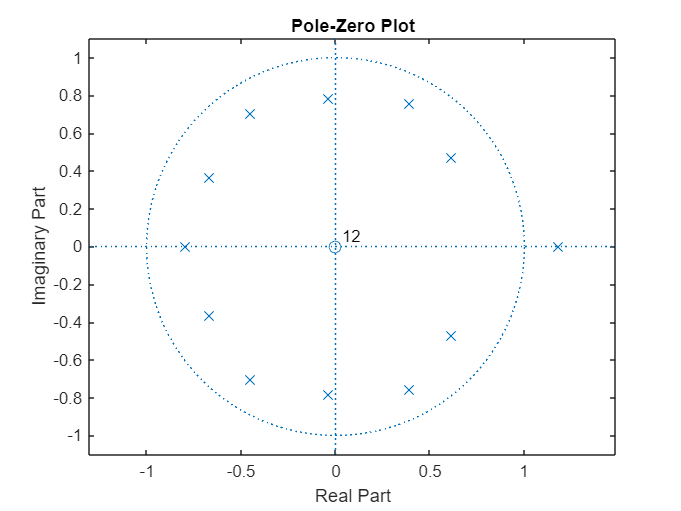

zplane(b2,a2)

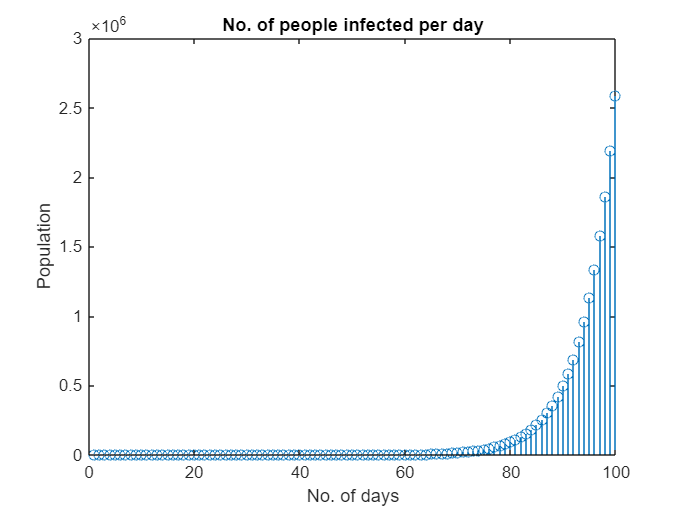

N2 = 1:100;
syms m
m = sym(1);
sol = kroneckerDelta(N2,m);
var = double(sol);
sys3 = filter( b2, a2, var); % impulse response using kronecker delta
stem(N2,sys3)
title("No. of people infected per day")
ylabel("Population")
xlabel("No. of days")

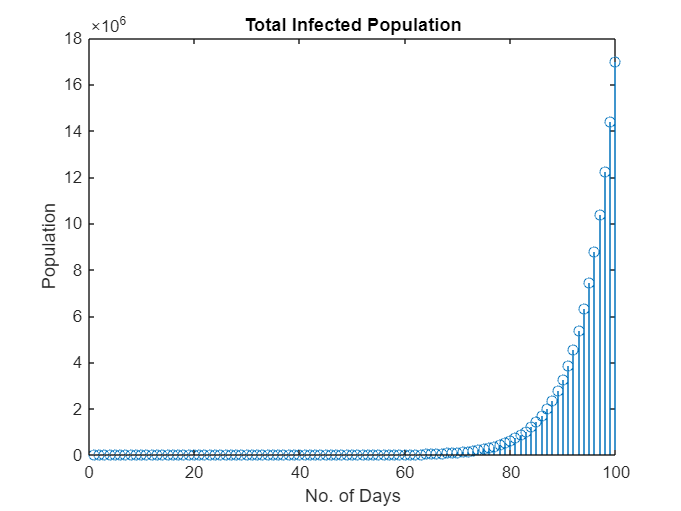

figure;
I2 = filter(b1,a1,sys3); % intergrator filter
stem(I2)
title("Total Infected Population")
ylabel("Population")
xlabel("No. of Days")

figure;
Total_infected_people_2 = I2(end)

Total_infected_people_2 = 1.6996e+07

Problem 2.2

sys3(94)

ans = 9.6058e+05

sys3(95)

ans = 1.1329e+06

% it takes 95 days to reach 1 million

Problem 3.1

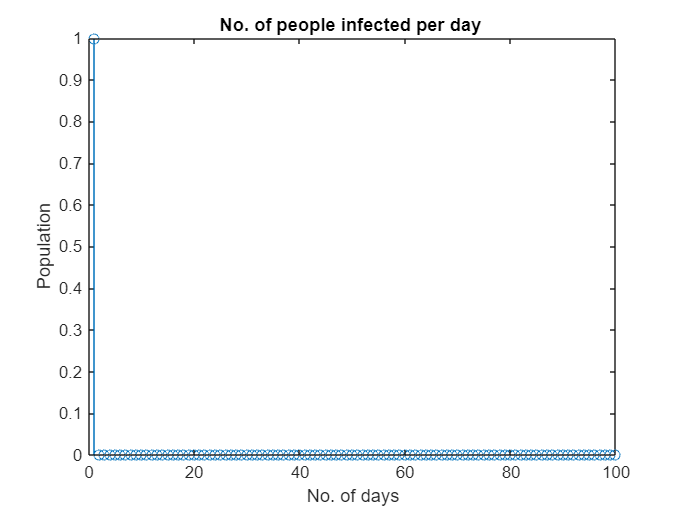

ak = [0.1,  0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b3 = 1;
rho =1;
a3 = [1 (1-rho)*ak];
sys4 = tf(b3,a3,1,"Variable" ,"z^-1");
N2 = 1:100;
syms m
m = sym(1);
sol = kroneckerDelta(N2,m);
var = double(sol);
sys5 = filter( b3, a3, var);
stem(N2,sys5)
title("No. of people infected per day ")
ylabel("Population")
xlabel("No. of days")

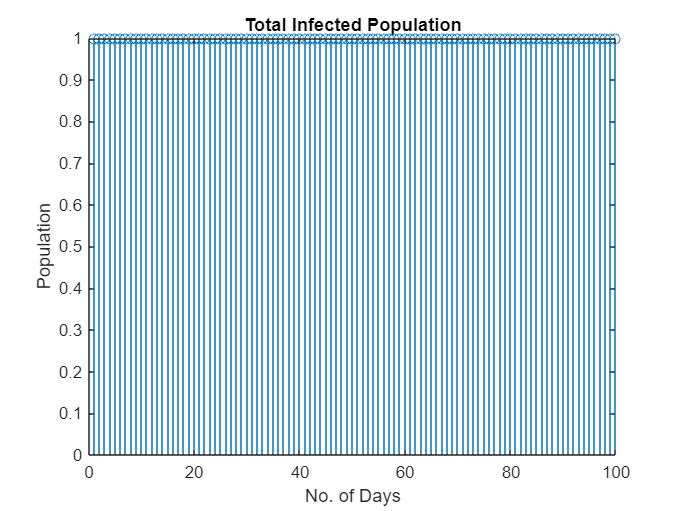

figure;
I3 = filter(b1,a1,sys5);
stem(I3)
title("Total Infected Population")
ylabel("Population")
xlabel("No. of Days")

figure;
Total_infected_people_3 = I3(end)

Total_infected_people_3 = 1

Problem 3.2

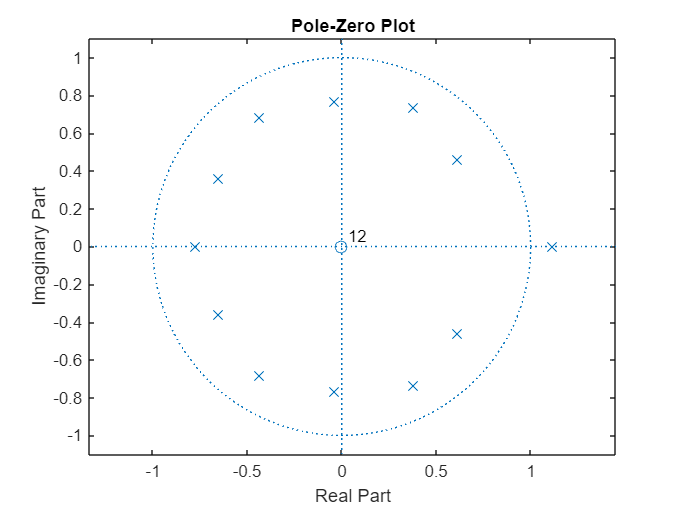

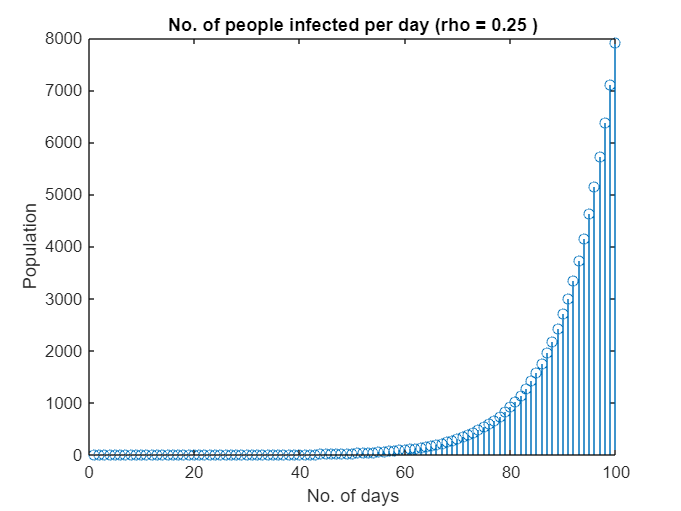

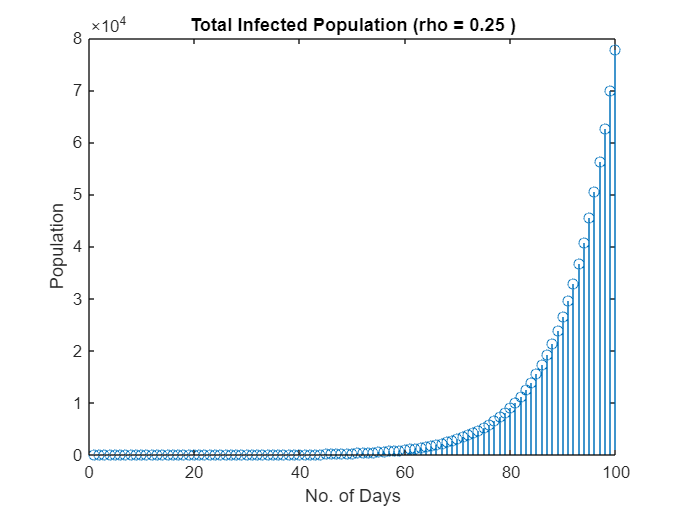

Total_infected_people_4 = 7.7745e+04

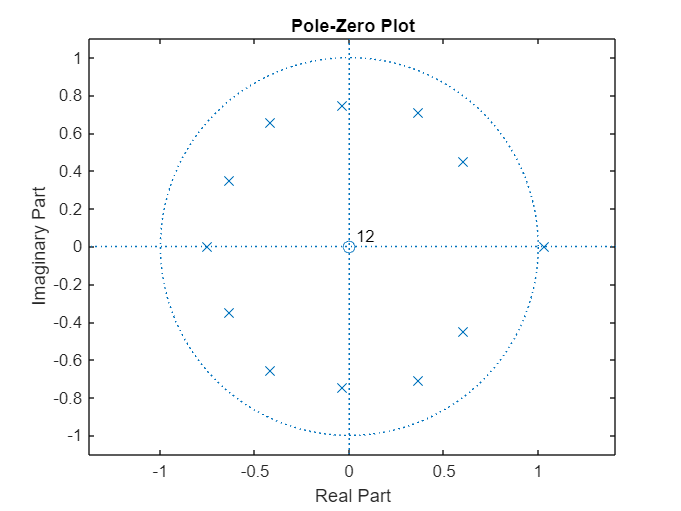

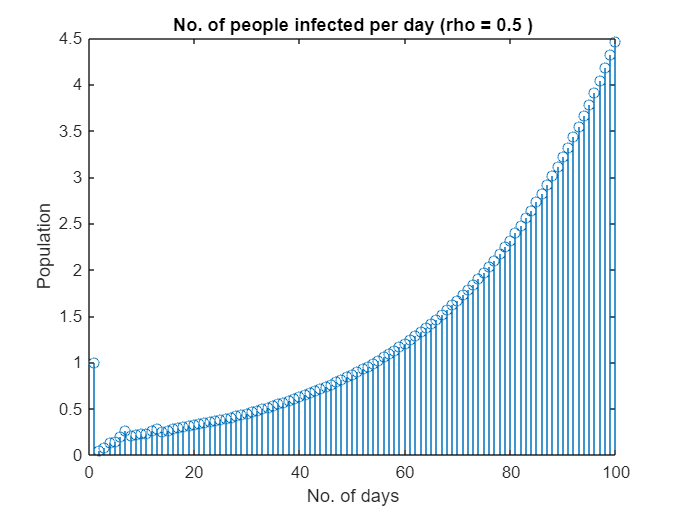

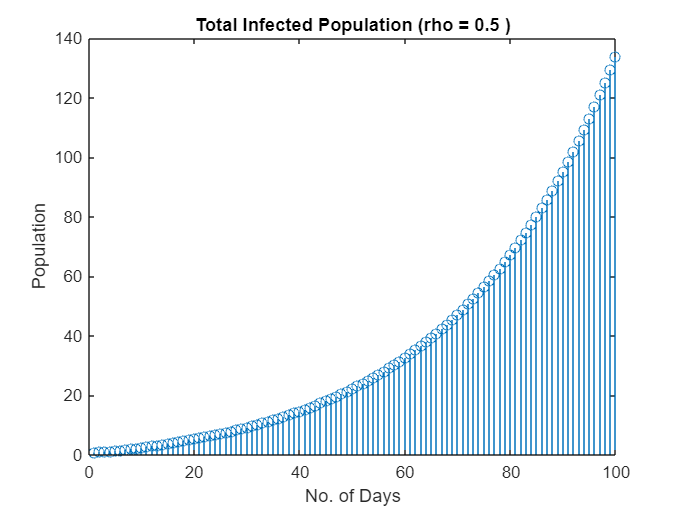

Total_infected_people_4 = 133.8987

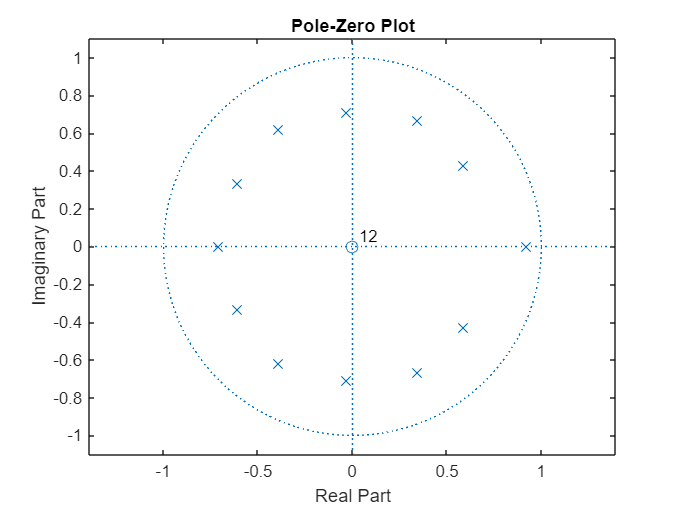

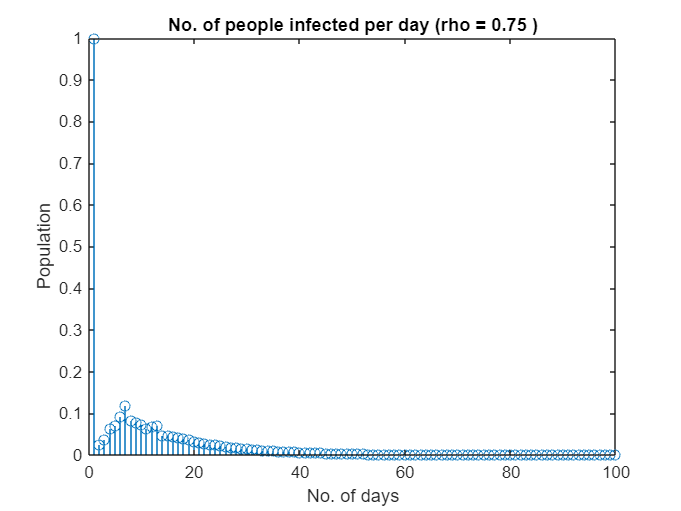

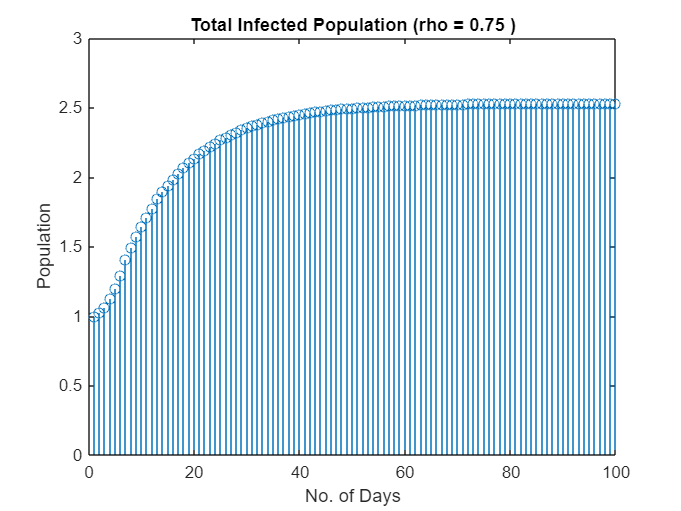

Total_infected_people_4 = 2.5310

ak = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
b4 = 1;
rho1 = [0.25 0.5 0.75];
N2 = 1:100;

for i = rho1 ;
    a4 = [1 -(1-i)*ak];
    zplane(b4, a4);
    figure;
    sys6 = tf(b4,a4,1,"Variable" ,"z^-1"); % defines transfer function
    sys7 = filter( b4, a4, var);
    stem(N2,sys7)
    title("No. of people infected per day (rho = "+i+" )")
    ylabel("Population")
    xlabel("No. of days")
    figure;
    I4 = filter(b1,a1,sys7);
    stem(I4)
    title("Total Infected Population (rho = "+i+" )")
    ylabel("Population")
    xlabel("No. of Days")
    figure;
    Total_infected_people_4 = I4(end)
end

Problem 4

% Problem 4

% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:101;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

Total_infections2 = 1.7840e+07

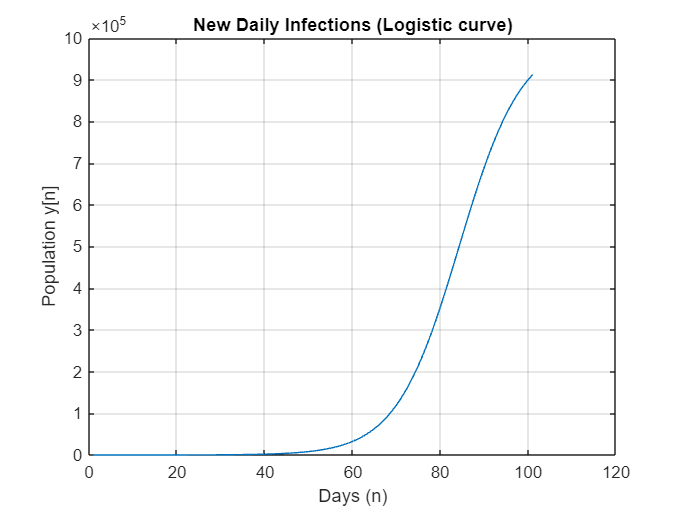


figure;
plot(n,logistic)
title("New Daily Infections (Logistic curve)")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on



% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value

Global_maximum = 3.4918e+04

Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value

Value_n = 85

Zero_crossing = n(round(filter_2) == 94) % Inflection point

Zero_crossing = 85

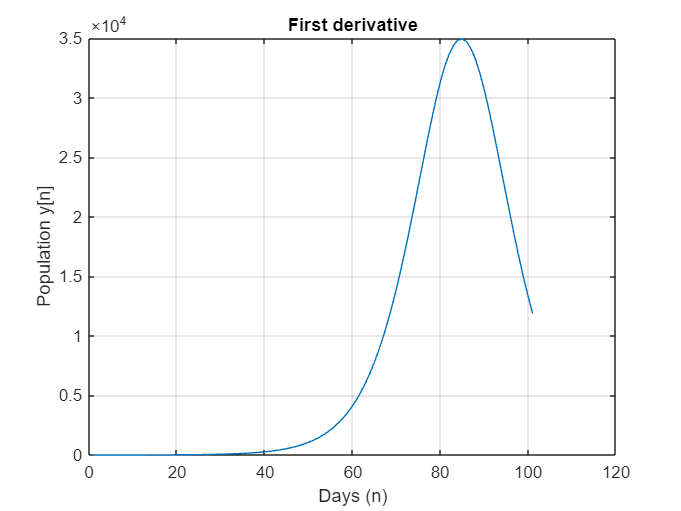


figure;
plot(n,filter_1)
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

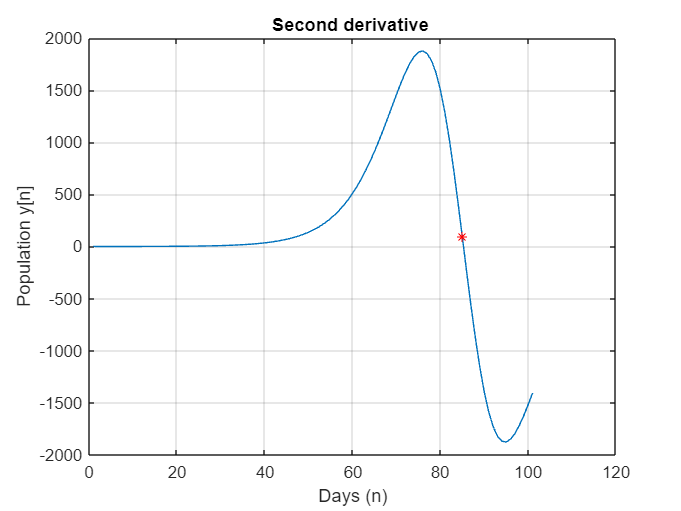


figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'r*')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on